# Figures of average acoustic features per female bat in Acoustic Group 1

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home-1/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BoxPath = '/Users/elie/Box';
Path2Paper = fullfile(BoxPath, 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicAudioGood','CallType','OnSetOffsetSample',...
    'BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','F0_cv','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean', 'AmpPeriodF','AmpPeriodP')
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
MicAudioGoodInd = find(MicAudioGood01);
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;
fprintf(1,'In total, there are %d Vocal elements, %d are also of good microphone quality\n', length(MicAudioGood01), sum(MicAudioGood01))

In total, there are 36227 Vocal elements, 28091 are also of good microphone quality


Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
Path2RecordingTable = fullfile(BoxPath,'JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Female';
    end

end
USexDeaf = {'Kanamycin Male' 'Saline Male' 'Kanamycin Female' 'Saline Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

Construct the table of PAF for statistical purposes

Tbl =  table(BatID(MicAudioGoodInd(TmicAll4==1)),...
    CallType(MicAudioGoodInd(TmicAll4==1)),...
    Sex(MicAudioGoodInd(TmicAll4==1)),...
    Deaf(MicAudioGoodInd(TmicAll4==1)),...
    DurationElmt(MicAudioGoodInd(TmicAll4==1)),...
    RMS_mean(MicAudioGoodInd(TmicAll4==1)),...
    Sal_mean(MicAudioGoodInd(TmicAll4==1)),...
    F0_mean(MicAudioGoodInd(TmicAll4==1))/1000,...
    F0_cv(MicAudioGoodInd(TmicAll4==1)),...
    Spect_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    Spect_std(MicAudioGoodInd(TmicAll4==1))/10^3,...
    Spect_kurt(MicAudioGoodInd(TmicAll4==1)),...
    Spect_skew(MicAudioGoodInd(TmicAll4==1)),...
    Spect_ent(MicAudioGoodInd(TmicAll4==1)),...
    Time_mean(MicAudioGoodInd(TmicAll4==1)),...
    Time_std(MicAudioGoodInd(TmicAll4==1)),...
    Time_kurt(MicAudioGoodInd(TmicAll4==1)),...
    Time_skew(MicAudioGoodInd(TmicAll4==1)),...
    Time_ent(MicAudioGoodInd(TmicAll4==1)),...
    Q1_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    Q2_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    Q3_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    SpectMic_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    SpectMic_std(MicAudioGoodInd(TmicAll4==1))/10^3,...
    SpectMic_kurt(MicAudioGoodInd(TmicAll4==1)),...
    SpectMic_skew(MicAudioGoodInd(TmicAll4==1)),...
    SpectMic_ent(MicAudioGoodInd(TmicAll4==1)),...
    Q1Mic_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    Q2Mic_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    Q3Mic_mean(MicAudioGoodInd(TmicAll4==1))/10^3,...
    log(AmpPeriodF(MicAudioGoodInd(TmicAll4==1))),...
    AmpPeriodP(MicAudioGoodInd(TmicAll4==1)),...
    'VariableNames', {'BatID', 'CT','Sex','HorD',...
    'Duration (ms)','RMS mean','Saliency (AU)','Fund (kHz)','Fund CV','S mean (kHz)','S std (kHz)','S kurt (Hz)','S skew (Hz)','S ent',...
    'T mean (ms)','T std (ms)','T kurt (ms)','T skew (ms)','T ent','1st SQ (kHz)','2nd SQ (kHz)','3rd SQ (kHz)','Mic S mean (kHz)','Mic S std (kHz)',...
    'Mic S kurt (Hz)','Mic S skew (Hz)','Mic S ent','Mic 1st SQ (kHz)','Mic 2nd SQ (kHz)','Mic 3rd SQ (kHz)','Amp P F (log Hz)','Amp P P'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});

Go through all acoustic categories and calculate and plot the average values of features for all individuals

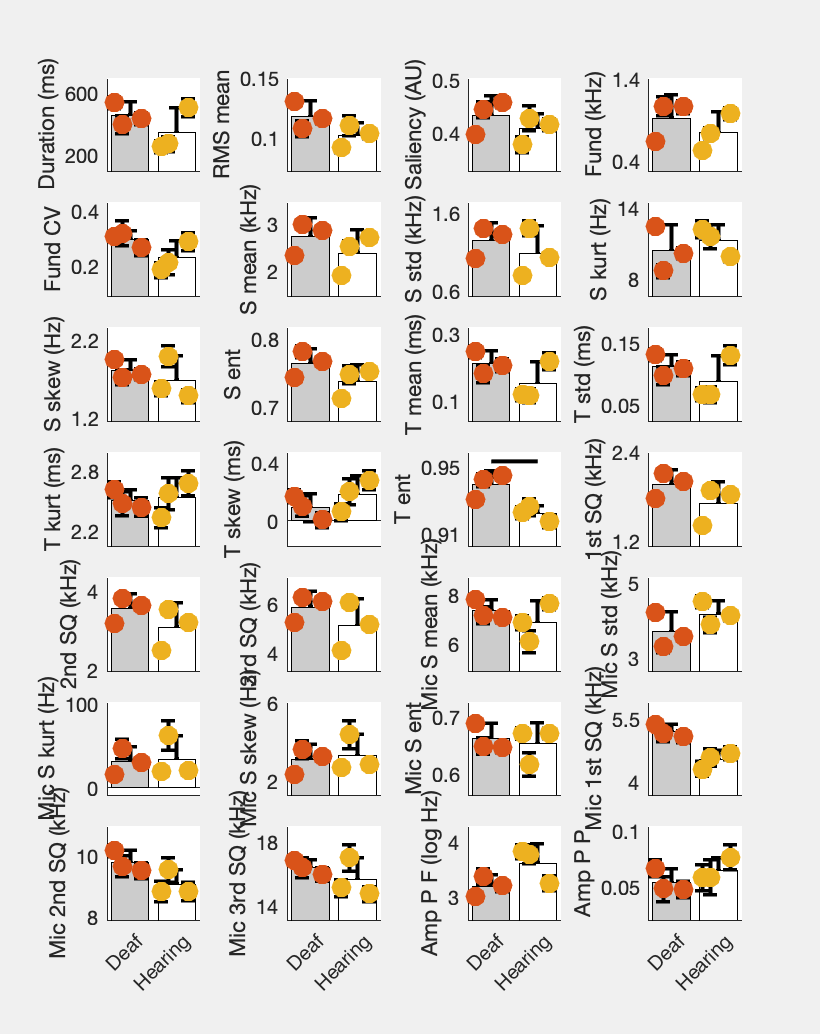

*********************     Calculations on Duration (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     3     38505    38523    -19250                                
    lme      4     38505    38529    -19249    1.8922    1          0.16895


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    38505    38529    -19249           38497   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}        347.99      53.249    6.5351    2532    7.6595e-11     243.57     452.4
    {'HorD_D'     }        111.27      74.731     1.489    2532       0.13661    -35.265    257.81

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lower     Upp

*********************     Calculations on RMS mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lmeR     3       -8133    -8115.5    4069.5                                 
    lme      4     -8134.9    -8111.5    4071.4    3.9049    1          0.048147


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -8134.9    -8111.5    4071.4           -8142.9 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower        Upper   
    {'(Intercept)'}        0.10165     0.0050603    20.088    2532    2.1251e-83     0.091726     0.11157
    {'HorD_D'     }        0.01689     0.0070948    2.3807    2532      0.017355    0.0029782    0.030803

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type       

*********************     Calculations on Saliency (AU)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -3302.1    -3284.6    1654.1                                
    lme      4     -3301.6    -3278.3    1654.8    1.4543    1          0.22784


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2523
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -3301.6    -3278.3    1654.8           -3309.6 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue         Lower        Upper   
    {'(Intercept)'}         0.40666    0.014346    28.346    2521    1.1389e-153      0.37853     0.43479
    {'HorD_D'     }        0.025776    0.020145    1.2795    2521        0.20083    -0.013727    0.065278

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type       

*********************     Calculations on Fund (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     4153.1    4170.3    -2073.6                                
    lme      4       4154      4177      -2073    1.0831    1          0.29801


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2308
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC     BIC     LogLikelihood    Deviance
    4154    4177    -2073            4146    

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower       Upper  
    {'(Intercept)'}        0.75154     0.11107    6.7666    2306    1.6667e-11     0.53374    0.96934
    {'HorD_D'     }        0.17015     0.15662    1.0863    2306       0.27744    -0.13699    0.47728

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lower   

*********************     Calculations on Fund CV   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue
    lmeR     3     859.13    876.36    -426.56                                
    lme      4     872.06    895.04    -432.03    -10.937    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2308
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    872.06    895.04    -432.03          864.06  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue         Lower      Upper   
    {'(Intercept)'}         0.23496    0.010008    23.477    2306    1.8058e-109    0.21534     0.25459
    {'HorD_D'     }        0.061143    0.012592    4.8558    2306     1.2795e-06    0.03645    0.085835

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on S mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     3295.3    3312.8    -1644.6                                
    lme      4     3295.8    3319.1    -1643.9    1.5173    1          0.21803


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3295.8    3319.1    -1643.9          3287.8  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower       Upper  
    {'(Intercept)'}         2.3819     0.18309     13.01    2532    1.6698e-37      2.0229     2.7409
    {'HorD_D'     }        0.33986     0.25877    1.3134    2532       0.18917    -0.16756    0.84728

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    

*********************     Calculations on S std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     3       1781    1798.5    -887.48                                 
    lme      4     1782.1    1805.4    -887.04    0.88794    1          0.34604


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1782.1    1805.4    -887.04          1774.1  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue       Lower      Upper 
    {'(Intercept)'}         1.0726     0.12369     8.6716    2532    7.474e-18    0.83002    1.3151
    {'HorD_D'     }        0.17105     0.17479    0.97858    2532      0.32788    -0.1717    0.5138

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lower 

*********************     Calculations on S kurt (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat     deltaDF    pValue 
    lmeR     3     15658    15675    -7825.9                                 
    lme      4     15659    15683    -7825.7    0.51768    1          0.47183


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    15659    15683    -7825.7          15651   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat       DF      pValue        Lower      Upper 
    {'(Intercept)'}          11.218    0.75285      14.901    2532    3.3737e-48      9.742    12.695
    {'HorD_D'     }        -0.77614     1.0598    -0.73237    2532       0.46401    -2.8542     1.302

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lowe

*********************     Calculations on S skew (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     3       6099    6116.5    -3046.5                                 
    lme      4     6100.1    6123.4      -3046    0.89915    1          0.34301


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6100.1    6123.4    -3046            6092.1  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue        Lower       Upper  
    {'(Intercept)'}         1.6755     0.097404     17.202    2532    8.3209e-63      1.4845     1.8665
    {'HorD_D'     }        0.13626      0.13687    0.99555    2532       0.31956    -0.13213    0.40466

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on S ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lmeR     3     -6992.4    -6974.9    3499.2                                 
    lme      4     -6993.3    -6969.9    3500.6    2.8749    1          0.089971


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6993.3    -6969.9    3500.6           -7001.3 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue      Lower          Upper   
    {'(Intercept)'}         0.73705    0.0098244    75.022    2532           0        0.71779     0.75631
    {'HorD_D'     }        0.026517     0.013844    1.9154    2532    0.055558    -0.00063032    0.053665

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type       

*********************     Calculations on T mean (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lmeR     3     -408.85    -391.34    207.43                                 
    lme      4     -409.66    -386.31    208.83    2.8093    1          0.093722


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -409.66    -386.31    208.83           -417.66 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower         Upper  
    {'(Intercept)'}         0.15403    0.022099    6.9702    2532    4.0206e-12        0.1107    0.19737
    {'HorD_D'     }        0.058508    0.030956    1.8901    2532      0.058865    -0.0021932    0.11921

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type          

*********************     Calculations on T std (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lmeR     3     -3305.8    -3288.3    1655.9                               
    lme      4     -3305.2    -3281.8    1656.6    1.359     1          0.2437


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -3305.2    -3281.8    1656.6           -3313.2 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower        Upper   
    {'(Intercept)'}        0.089109    0.013437    6.6315    2532    4.0469e-11      0.06276     0.11546
    {'HorD_D'     }        0.023234    0.018847    1.2327    2532       0.21779    -0.013724    0.060192

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type          

*********************     Calculations on T kurt (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat       deltaDF    pValue 
    lmeR     3     7807.7    7825.2    -3900.9                                   
    lme      4     7809.7    7833.1    -3900.9    0.0019099    1          0.96514


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    7809.7    7833.1    -3900.9          7801.7  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF      pValue     Lower        Upper   
    {'(Intercept)'}           2.5352    0.036656      69.162    2532          0       2.4633      2.6071
    {'HorD_D'     }        0.0020242    0.046319    0.043702    2532    0.96515    -0.088802    0.092851

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on T skew (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     4616.6    4634.2    -2305.3                                
    lme      4     4617.1    4640.5    -2304.6    1.5145    1          0.21846


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    4617.1    4640.5    -2304.6          4609.1  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}          0.18024    0.048242    3.7361    2532    0.00019104    0.085638     0.27483
    {'HorD_D'     }        -0.087801    0.067231    -1.306    2532       0.19168    -0.21963    0.044032

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on T ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -9881.1    -9863.6    4943.5                                  
    lme      4     -9886.9    -9863.6    4947.5    7.8172    1          0.0051751


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -9886.9    -9863.6    4947.5           -9894.9 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower        Upper   
    {'(Intercept)'}          0.9221    0.0031053    296.94    2532             0      0.91601     0.92818
    {'HorD_D'     }        0.017172    0.0043413    3.9554    2532    7.8494e-05    0.0086588    0.025684

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type       

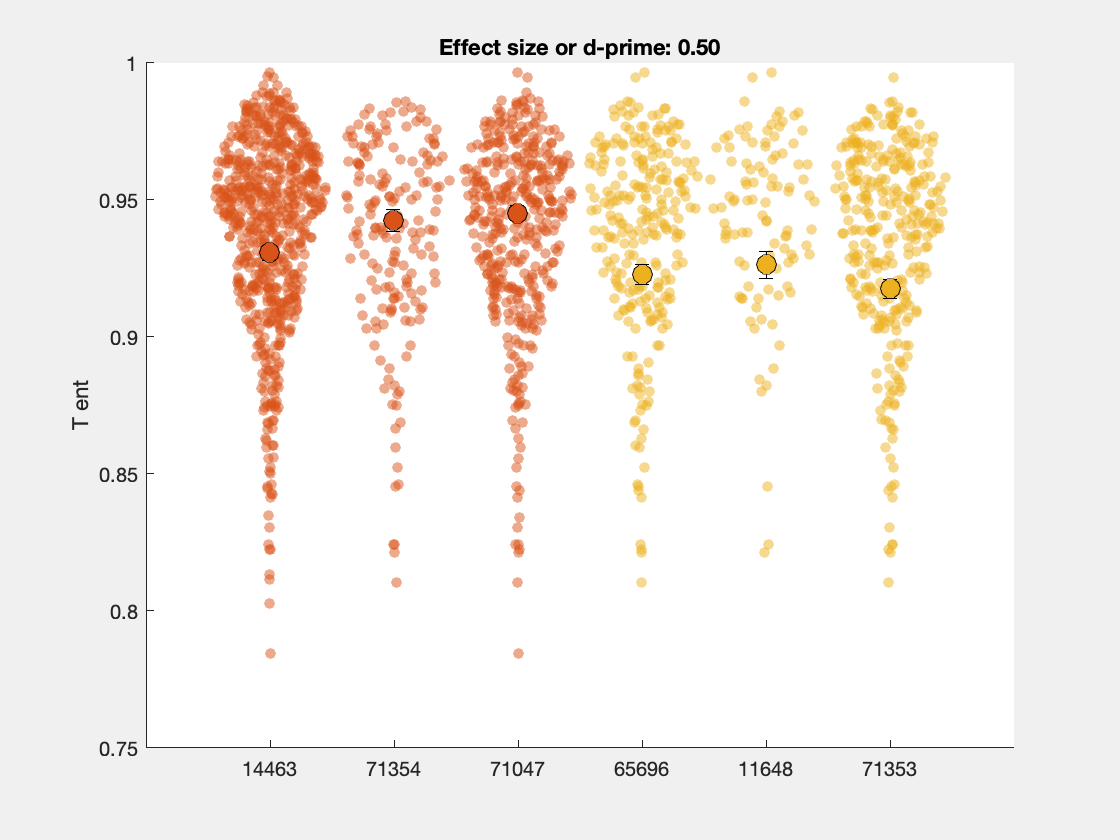

*********************     Calculations on 1st SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -27.713    -10.202    16.857                                
    lme      4     -28.183    -4.8341    18.091    2.4696    1          0.11607


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2533
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -28.183    -4.8341    18.091           -36.183 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower        Upper  
    {'(Intercept)'}          1.707     0.10396    16.419    2531    1.1968e-57       1.5031     1.9108
    {'HorD_D'     }        0.25685     0.14695    1.7479    2531      0.080605    -0.031303    0.54501

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estim

*********************     Calculations on 2nd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     3203.6    3221.1    -1598.8                                
    lme      4     3203.5    3226.9    -1597.8    2.0857    1          0.14868


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2533
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3203.5    3226.9    -1597.8          3195.5  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower       Upper 
    {'(Intercept)'}         3.0759      0.2078    14.802    2531    1.3077e-47      2.6684    3.4833
    {'HorD_D'     }        0.46397     0.29374    1.5795    2531       0.11434    -0.11202      1.04

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Low

*********************     Calculations on 3rd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     5742.8    5760.3    -2868.4                                
    lme      4       5743    5766.3    -2867.5    1.846     1          0.17424


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2533
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    5743    5766.3    -2867.5          5735    

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower       Upper 
    {'(Intercept)'}         5.1187     0.36828    13.899    2531    2.2277e-42      4.3965    5.8408
    {'HorD_D'     }        0.76563     0.52062    1.4706    2531       0.14152    -0.25526    1.7865

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Mic S mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lmeR     3     11634    11651      -5814                                
    lme      4     11635    11658    -5813.3    1.2498    1          0.26359


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11635    11658    -5813.3          11627   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower      Upper 
    {'(Intercept)'}         6.8937     0.29047    23.733    2532    1.3533e-112     6.3241    7.4632
    {'HorD_D'     }        0.47968     0.40817    1.1752    2532        0.24003    -0.3207    1.2801

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Mic S std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     8116.8    8134.4    -4055.4                                
    lme      4     8116.3    8139.6    -4054.1    2.578     1          0.10836


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    8116.3    8139.6    -4054.1          8108.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue        Lower      Upper   
    {'(Intercept)'}          4.1778    0.19002     21.986    2532    3.4036e-98     3.8052      4.5504
    {'HorD_D'     }        -0.47934    0.26773    -1.7904    2532      0.073514    -1.0043    0.045656

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate 

*********************     Calculations on Mic S kurt (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat      deltaDF    pValue
    lmeR     3     27445    27462    -13719                                 
    lme      4     27447    27470    -13719    0.059808    1          0.8068


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    27447    27470    -13719           27439   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF      pValue        Lower      Upper 
    {'(Intercept)'}         33.91      9.5028      3.5684    2532    0.00036579     15.276    52.544
    {'HorD_D'     }        -3.284      13.398    -0.24511    2532       0.80639    -29.557    22.989

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Mic S skew (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lmeR     3     11544    11562    -5769.2                                
    lme      4     11546    11570    -5769.1    0.1602    1          0.68898


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11546    11570    -5769.1          11538   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat       DF      pValue        Lower      Upper 
    {'(Intercept)'}          3.2982    0.38464      8.5749    2532    1.6985e-17      2.544    4.0525
    {'HorD_D'     }        -0.21833    0.54206    -0.40278    2532       0.68714    -1.2813    0.8446

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lowe

*********************     Calculations on Mic S ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3       -4711    -4693.4    2358.5                                 
    lme      4     -4709.1    -4685.8    2358.6    0.18778    1          0.66477


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -4709.1    -4685.8    2358.6           -4717.1 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue    Lower        Upper   
    {'(Intercept)'}          0.65409    0.012997     50.326    2532         0       0.6286     0.67957
    {'HorD_D'     }        0.0079807    0.018288    0.43638    2532    0.6626    -0.027881    0.043842

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estim

*********************     Calculations on Mic 1st SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     9386.5      9404    -4690.3                                
    lme      4     9386.3    9409.6    -4689.1    2.2372    1          0.13472


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2533
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    9386.3    9409.6    -4689.1          9378.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}         4.5239     0.050068    90.355    2531             0     4.4257    4.6221
    {'HorD_D'     }        0.71383     0.063275    11.281    2531    7.8097e-29    0.58975    0.8379

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate      L

*********************     Calculations on Mic 2nd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat     deltaDF    pValue
    lmeR     3     12452    12469      -6223                                
    lme      4     12463    12486    -6227.3    -8.6651    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2533
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12463    12486    -6227.3          12455   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}          8.992     0.091893    97.852    2531             0     8.8118    9.1722
    {'HorD_D'     }        0.89891      0.11613    7.7405    2531    1.4206e-14    0.67119    1.1266

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate      Lower

*********************     Calculations on Mic 3rd SQ (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue
    lmeR     3     15082    15099    -7537.8                               
    lme      4     15082    15105      -7537    1.7137    1          0.1905


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2533
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    15082    15105    -7537            15074   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower       Upper 
    {'(Intercept)'}         15.571     0.41368    37.641    2531    1.2528e-246       14.76    16.382
    {'HorD_D'     }        0.83383     0.57783     1.443    2531        0.14914    -0.29924    1.9669

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estimate    Lowe

*********************     Calculations on Amp P F (log Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     7932.8    7950.3    -3963.4                                
    lme      4     7930.6    7953.9    -3961.3    4.1748    1          0.04103


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2505
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    7930.6    7953.9    -3961.3          7922.6  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue        Lower      Upper    
    {'(Intercept)'}         3.6137     0.12367     29.222    2503    9.141e-162     3.3712       3.8562
    {'HorD_D'     }        -0.4252     0.17334    -2.4531    2503      0.014233    -0.7651    -0.085306

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on Amp P P   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lmeR     3     -4299.3    -4281.8    2152.7                                 
    lme      4     -4301.5    -4278.2    2154.8    4.1578    1          0.041444


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2534
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -4301.5    -4278.2    2154.8           -4309.5 

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat      DF      pValue        Lower        Upper      
    {'(Intercept)'}            0.0664    0.0033596     19.764    2532    5.6725e-81     0.059812       0.072988
    {'HorD_D'     }        -0.0086599    0.0042453    -2.0399    2532      0.041464    -0.016985    -0.00033535

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2           

% List of variables
AcVars = Tbl.Properties.VariableNames(5:end);
Pvalue_matrix_LME = nan(length(AcVars),1);
Effect_size = nan(length(AcVars),1);
BatFemales = BatName(contains(BatSexDeaf, 'Female'));
BatSexDeafFemales = BatSexDeaf(contains(BatSexDeaf, 'Female'));
AcVar_mean_pBat = nan(length(AcVars), size(BatFemales,2));
AcVar_se_pBat = nan(length(AcVars), size(BatFemales,2));
AcVar_std_pBat = nan(length(AcVars), size(BatFemales,2));
N_pBat = nan(length(AcVars), size(BatFemales,2));
Col_pBat = cell(length(AcVars),1);
AcVarMean_HD = nan(length(AcVars),2);
AcVarSE_HD = nan(length(AcVars),2);


Fig1=figure(1);
clf
set(gcf,'Visible','on')
T=tiledlayout(7,4,'TileSpacing','compact');

INN = contains(Tbl.Sex, 'F');
for vv=1:length(AcVars)
    fprintf(1, '*********************     Calculations on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    Tbl_local = table(Tbl.BatID(INN), Tbl.CT(INN), Tbl.HorD(INN), AcVar(INN), 'VariableNames', {'BatID', 'CT','HorD', 'AcVar'});
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    Tbl_local.AcVar(isinf(Tbl_local.AcVar))=nan;
    
    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ 1 + (1|BatID)');
    TestLME_HD=compare(lmeR, lme)
    Pvalue_matrix_LME(vv) = TestLME_HD.pValue(2);

    lme

    % Nice plot 1
    Col_pBat{vv} = nan(length(BatFemales),3);
    for bb=1:length(BatFemales)
        Ind = strcmp(Tbl_local.BatID,num2str(BatFemales(bb)));
        
        AcVar_mean_pBat(vv,bb) = mean(Tbl_local.AcVar(Ind), 'omitnan');
        AcVar_se_pBat(vv,bb) = std(Tbl_local.AcVar(Ind), 'omitnan')/sum(~isnan(Tbl_local.AcVar(Ind)))^0.5;
        AcVar_std_pBat(vv,bb) = std(Tbl_local.AcVar(Ind), 'omitnan');
        N_pBat(vv,bb) = sum(~isnan(Tbl_local.AcVar(Ind)));
        Col_pBat{vv}(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeafFemales{bb}),:);
    end

   
    AcVarMean_HD(vv,:) = [mean(AcVar_mean_pBat(vv,contains(BatSexDeafFemales, 'Kanamycin'))) mean(AcVar_mean_pBat(vv,contains(BatSexDeafFemales, 'Saline')))];
    AcVarSE_HD(vv,:) = [std(AcVar_mean_pBat(vv,contains(BatSexDeafFemales, 'Kanamycin')))/sum(contains(BatSexDeafFemales, 'Kanamycin'))^0.5 std(AcVar_mean_pBat(vv,contains(BatSexDeafFemales, 'Saline')))/sum(contains(BatSexDeafFemales, 'Saline'))^0.5];
    
    figure(1);
    N=nexttile(vv,[1,1]);
    XHorD = [0.33 0.66 1.5 2.33 2.66 3.5];
%     XHorD(contains(BatSexDeafFemales, 'Saline')) = XHorD(contains(BatSexDeafFemales, 'Saline'))+2;
    errorbar([1 3],AcVarMean_HD(vv,:), 2*AcVarSE_HD(vv,:), 2*AcVarSE_HD(vv,:), 'k.','LineWidth',2)
    hold on
    B=bar([1 3], AcVarMean_HD(vv,:));
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 'k.','LineWidth',2)
    hold on
    scatter(XHorD,AcVar_mean_pBat(vv,:),100, Col_pBat{vv}, 'filled')
    ylabel(sprintf('%s', AcVars{vv}), 'FontSize',12)
    XLim = [0 4];
    set(gca, 'XLim', XLim);
    MinVal = min(AcVar_mean_pBat(vv,:)-2*AcVar_se_pBat(vv,:));
    MaxVal = max(AcVar_mean_pBat(vv,:)+2*AcVar_se_pBat(vv,:));
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
%     YLim(1) = MinVal - (MaxVal-MinVal)*2/3;
    set(gca, 'YLim', YLim)
%     if vv==length(AcVars)
%         for ct=1:length(USexDeaf(1:2))
%             text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
%         end
%     end
    if vv>24
        set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'}, 'FontSize',12)
    else
        set(gca, 'XTick', [1 3],'XTickLabel', {'' ''})
    end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)], 'FontSize',10)
    hold off
    if ~(TestLME_HD.pValue(2) <0.01)
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
%         T.FontWeight = 'normal';
%         T.Color = 0.7.*ones(1,3);
    else
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        hold on
        plot([1 3], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
%         text(2,(19/20*diff(YLim) + YLim(1)), '<.01','FontSize', 9)
    end
    N.Box = 0;
    

    %         nexttile
    %         errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
    %         hold on
    %         scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
    %         ylabel(sprintf('%s (z-scored)', AcVars{vv}))
    %         XLim = [0 4];
    %         set(gca, 'XLim', XLim);
    %         YLim = get(gca, 'YLim');
    %         for ct=1:length(USexDeaf)
    %             text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
    %         end
    %         set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
    %         hold off
    %         title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))
    if Pvalue_matrix_LME(vv)<0.01
        Effect_size(vv) = lme.Coefficients.Estimate(2)/(sum((AcVar_std_pBat(vv,:).^2).*N_pBat(vv,:))./sum(N_pBat(vv,:)))^0.5;
        figure()
        set(gcf,'Visible','on')
        % Nice plot per bat
        
        for bb=1:length(BatFemales)
            Ind = INN(strcmp(Tbl.BatID(INN),num2str(BatFemales(bb))));
            hold on
            swarmchart(bb*ones(sum(Ind),1),AcVar(Ind),30,Col_pBat{vv}(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
        end
    
        hold on
        errorbar(1:6,AcVar_mean_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 'k.')
        hold on
        scatter(1:6,AcVar_mean_pBat(vv,:),100, Col_pBat{vv}, 'filled', 'MarkerEdgeColor', 'k')
        ylabel(sprintf('%s', AcVars{vv}));
        set(gca, 'XTick', 1:6,'XTickLabel', BatFemales)
        hold off
        title(sprintf('Effect size or d-prime: %.2f', Effect_size(vv)))
    end



end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

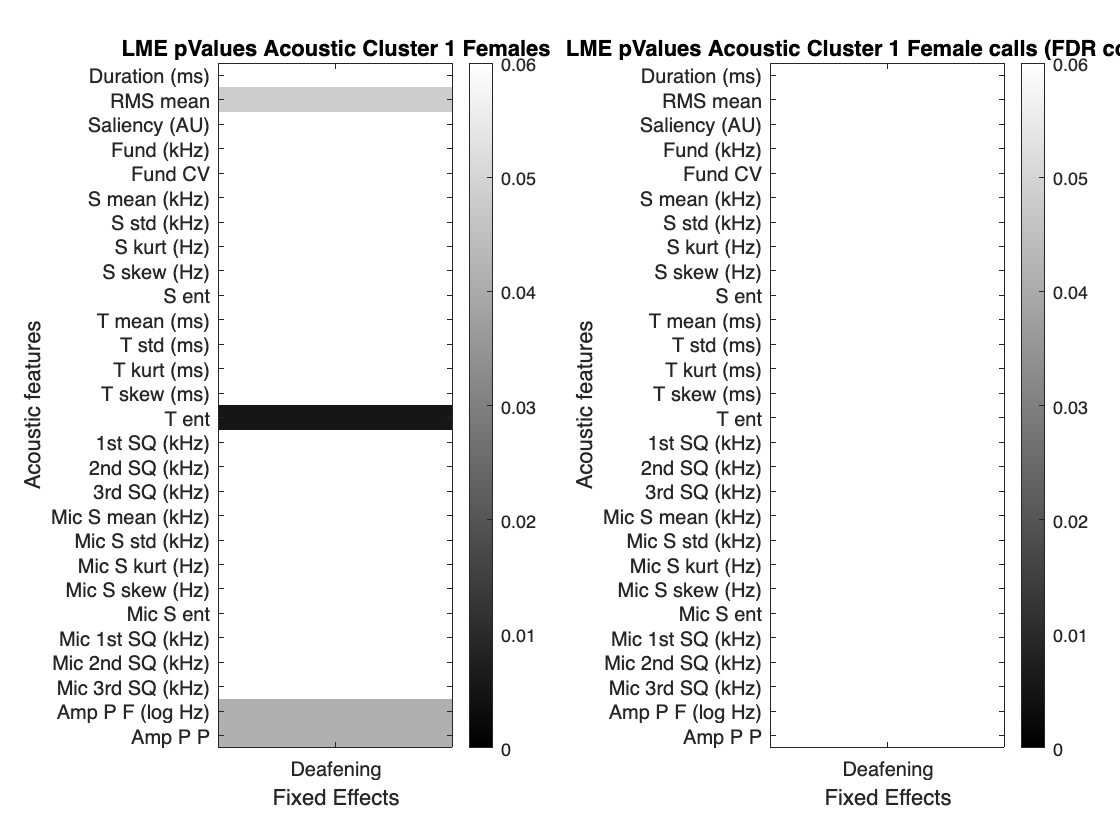

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank)) within each acoustic cluster
NVars = size(Pvalue_matrix_LME,1);

Pvalue_vector = Pvalue_matrix_LME;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrix_LME_FDR = Pvalue_vectorFDR;

figure()
tiledlayout(1,2)
nexttile
Im = imagesc(Pvalue_matrix_LME);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 1 Females')
nexttile
Im = imagesc(Pvalue_matrix_LME_FDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 1 Female calls (FDR corrected)')

Pvalue_matrix_LME

Pvalue_matrix_LME =     0.1690
    0.0481
    0.2278
    0.2980
    1.0000
    0.2180
    0.3460
    0.4718
    0.3430
    0.0900


Pvalue_matrix_LME(Pvalue_matrix_LME<0.01)

ans = 0.0052

Pvalue_matrix_LME_FDR

Pvalue_matrix_LME_FDR =     2.8722
    1.1555
    2.7341
    2.6821
    1.0000
    3.0525
    2.4223
    2.8310
    2.7441
    2.0693


Pvalue_matrix_LME_FDR(Pvalue_matrix_LME<0.01)

ans = 0.1397

for vv=1:length(AcVars)
    if Pvalue_matrix_LME_FDR(vv)<0.01
        fprintf(1,'** %s %.4f %.4f **\n',AcVars{vv},Pvalue_matrix_LME(vv),Pvalue_matrix_LME_FDR(vv))
    elseif Pvalue_matrix_LME(vv)<0.01
        fprintf(1,'* %s %.4f %.4f *\n',AcVars{vv},Pvalue_matrix_LME(vv),Pvalue_matrix_LME_FDR(vv))
    else
        fprintf(1,'%s %.4f %.4f\n',AcVars{vv},Pvalue_matrix_LME(vv),Pvalue_matrix_LME_FDR(vv))
    end
end

Duration (ms) 0.1690 2.8722
RMS mean 0.0481 1.1555
Saliency (AU) 0.2278 2.7341
Fund (kHz) 0.2980 2.6821
Fund CV 1.0000 1.0000
S mean (kHz) 0.2180 3.0525
S std (kHz) 0.3460 2.4223
S kurt (Hz) 0.4718 2.8310
S skew (Hz) 0.3430 2.7441
S ent 0.0900 2.0693
T mean (ms) 0.0937 2.0619
T std (ms) 0.2437 2.6807
T kurt (ms) 0.9651 1.9303
T skew (ms) 0.2185 2.8399


* T ent 0.0052 0.1397 *


1st SQ (kHz) 0.1161 2.3213
2nd SQ (kHz) 0.1487 2.6762
3rd SQ (kHz) 0.1742 2.7879
Mic S mean (kHz) 0.2636 2.6359
Mic S std (kHz) 0.1084 2.2755
Mic S kurt (Hz) 0.8068 2.4204
Mic S skew (Hz) 0.6890 2.7559
Mic S ent 0.6648 3.3239
Mic 1st SQ (kHz) 0.1347 2.5597
Mic 2nd SQ (kHz) 1.0000 1.0000
Mic 3rd SQ (kHz) 0.1905 2.8575
Amp P F (log Hz) 0.0410 1.0668
Amp P P 0.0414 1.0361


Add the p-avlues after FDR correcion to the figure

for vv=1:length(AcVars)
    YLabel = Fig1.Children.Children(vv).YLabel.String;
    IndAcVars = contains(AcVars,YLabel);
    if sum(IndAcVars>1)
        keyboard % we should not end up here
    end
    if Pvalue_matrix_LME(IndAcVars)<0.01
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        YLim = Fig1.Children.Children(vv).YLim;
        hold on
        text(Fig1.Children.Children(vv),1.25,(diff(YLim) + YLim(1)), sprintf('p=%.3f', Pvalue_matrix_LME_FDR(IndAcVars)),'FontSize', 9)
    end
end

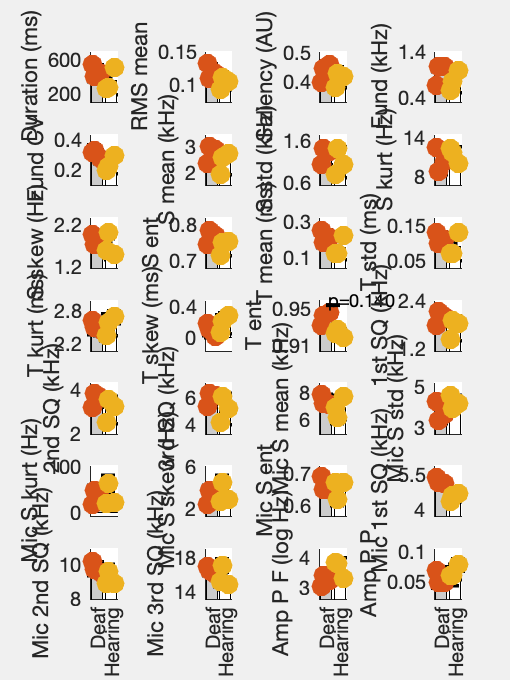

Fig1.Units = 'centimeters';
Fig1.Position(3:4) = [9 12];
Fig1.PaperSize = [9 12];
save(fullfile(LocalDataDir, "Data4_SupFigue2_PAF_FemalesAcGroup1_Calls"), 'AcVar_mean_pBat','AcVar_se_pBat','Col_pBat', 'AcVarMean_HD', 'AcVarSE_HD', 'BatSexDeafFemales', 'AcVars', 'USexDeaf', 'AcVar_std_pBat' ,'N_pBat', 'Pvalue_matrix_LME', 'Pvalue_matrix_LME_FDR', 'Effect_size');
print(Fig1,fullfile(Path2Paper,'SupFigure15_PAF_FemalesAcGroup1_TmicAll4.pdf'),'-dpdf','-fillpage')